Расчётно-графическая работа. Рисунок - 5, вариант - 5

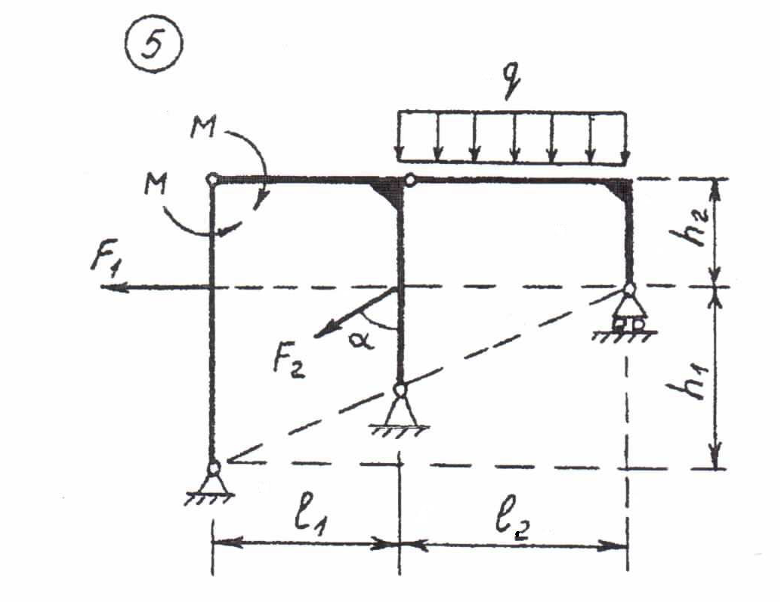

Система 3 тел, на каждое тело по 3 уравнения равновесия, всего уравнений - 9

Кол-во реакций: 4 реакции от двух опорно-неподвижных опор, 1 реакция от одной роликовой опоры, 4 реакции от двух шарниров. Итого, $\sum = 9$

9 = 9, следовательно система статически определима

Рассмотрим 1 тело:

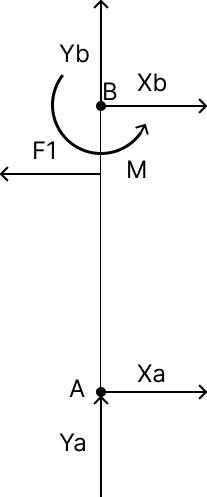

Составим систему уравнений:


$$\begin{cases}
\sum X: X_A+ X_B - F_1 = 0 \\
\sum Y: Y_A + Y_B = 0 \\
\sum M(A):F_1  h_1 + M - X_B(h_1 + h_2) = 0 \\
\end{cases}$$


Рассмотрим 2 тело:

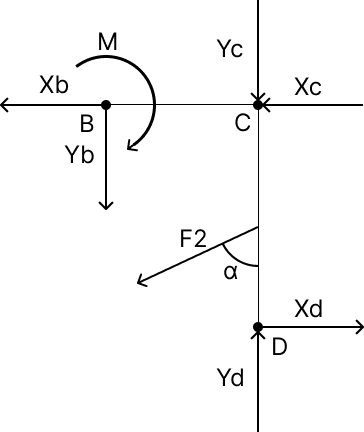

Составим систему уравнений:


$$\begin{cases}
\sum X: -X_B -X_C + X_D - F_2\sin{\alpha} = 0 \\
\sum Y: -Y_B - Y_C + Y_D - F_2\cos{\alpha} = 0 \\
\sum M(C) : -M + Y_B l_1 + X_D(h_2+ \frac{h_1l_2}{l_1+l_2})
 - F_2h_2\sin{\alpha}= 0 \\
\end{cases}$$


Рассмотрим 3 тело:

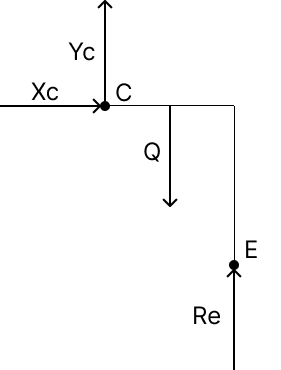

Составим систему уравнений:


$$\begin{cases}
\sum X: X_C= 0 \\
\sum Y: Y_C + R_E - Q = 0 \\
\sum M(C) : -Q \frac {l_2} 2+ R_El_2  = 0\\
\end{cases}$$


Решим систему линейных алгебраических уравнений:

clear;
syms Xa Ya Xb Yb Xc Yc Xd Yd Re;

F1 = 100;
F2 = 120;
alpha = 60;
q = 25;
M = 120;
l1 = 6;
l2 = 4;
h1 = 6;
h2 = 3;

x = (l2 * h1) / (l1 + l2);

Q = q * l2;

eqn1 = Xa + Xb - F1 == 0;
eqn2 = Ya + Yb == 0;
eqn3 = F1*h1 + M - Xb*(h1 + h2) == 0;

eqn4 = -Xb - Xc + Xd - F2*sind(alpha) == 0;
eqn5 = -Yb - Yc + Yd - F2*cosd(alpha) == 0;
eqn6 = -M + Yb*l1 + Xd * (h2 + x) - F2*sind(alpha)*h2 == 0;

eqn7 = Xc == 0;
eqn8 = Yc + Re - Q == 0;
eqn9 = -Q*l2/2 + Re*l2 == 0;

[A, B] = equationsToMatrix ([eqn1, eqn2, eqn3, eqn4, eqn5, eqn6, eqn7, eqn8, eqn9], [Xa, Ya, Xb, Yb, Xc, Yc, Xd, Yd, Re]);
X = linsolve(A, B)

$$X = \left(\begin{array}{c} 20\\ 24\,\sqrt{3}+52\\ 80\\ -24\,\sqrt{3}-52\\ 0\\ 50\\ 60\,\sqrt{3}+80\\ 58-24\,\sqrt{3}\\ 50 \end{array}\right)$$

Проверка:


$$\sum M(C) = -Y_Al_1+X_A(h1+h2)-F_1h_2-F_2h_2\sin{\alpha}+X_D(h_2+x)-Q \frac {l_2} 2+R_El_2$$


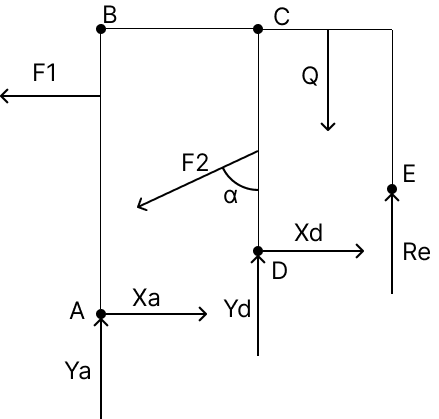

check = double(-X(2)*l1 + X(1)*(h1+h2) -F1*h2 - F2*h2*sind(alpha) + X(7)*(h2+x) - Q*l2/2 + X(9)*l2)

check = 0

Ответы:

Xa = X(1)

$$Xa = 20$$

Ya = X(2)

$$Ya = 24\,\sqrt{3}+52$$

Xa = X(3)

$$Xa = 80$$

Ya = X(4)

$$Ya = -24\,\sqrt{3}-52$$

Xa = X(5)

$$Xa = 0$$

Ya = X(6)

$$Ya = 50$$

Xa = X(7)

$$Xa = 60\,\sqrt{3}+80$$

Ya = X(8)

$$Ya = 58-24\,\sqrt{3}$$

Re = X(9)

$$Re = 50$$